clear all; close all; clc;

% Continuous (symbolic)
syms f t
f = sin(t);
f_diff = diff(f);

% Discrete
n = 5;
t_disc = linspace(0,2*pi,n);
T = t_disc(2) - t_disc(1)

T = 1.5708

f_sampling = 1/T

f_sampling = 0.6366

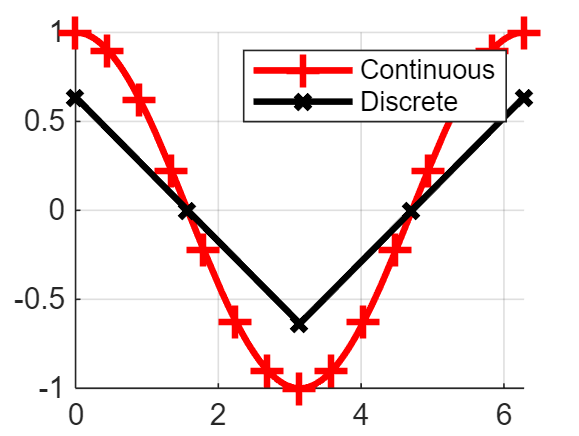

f_disc = sin(t_disc);
f_disc_diff = gradient(f_disc,t_disc); 


% Plotting
% fplot(t,f,[0,2*pi],'-ko','LineWidth',2,'MarkerSize',10)
hold on
% plot(t_disc,f_disc,'-x','LineWidth',2)
hold on
fplot(t,f_diff,[0,2*pi],'-+r','LineWidth',2,'MarkerSize',10)
hold on
plot(t_disc,f_disc_diff,'-kx','LineWidth',2)
legend('Continuous','Discrete')
grid on


% Decreasing sampling frequency seems to improve
% discrete approximation of the continuous derivative function
